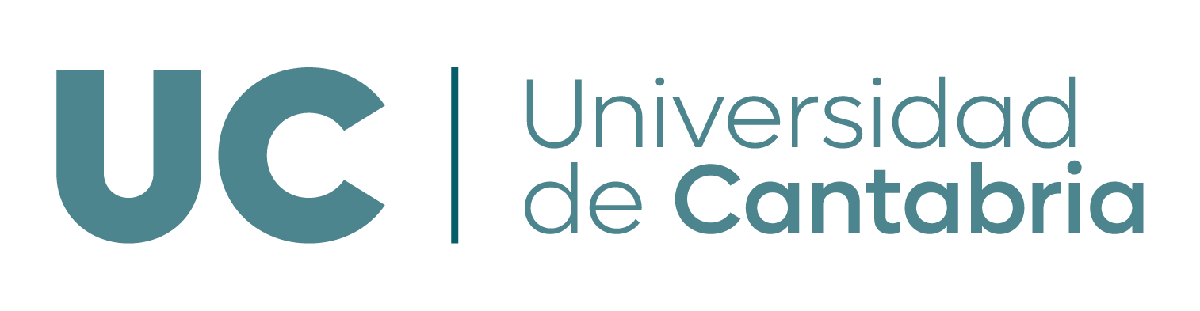

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Espacios Vectoriales Euclídeos**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Operar con productos escalares en MATLAB

- Obtener el complemento ortogonal de un subespacio dado

- Calcular bases ortogonales (y ortonormales)

- Calcular y utilizar la matriz de proyección sobre un cierto subespacio

- Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados

- Ajuste a una nube de puntos

**Funciones de MATLAB utilizadas en este guion: **`dot, norm ,acosd , null, orth`

## **1. Producto escalar, norma y ángulo**

### Producto escalar

En MATLAB, el producto escalar de dos vectores e $\mathbb{R}^n$ se puede obtener multiplicando matricialmente un vector fila por un vector columna. 

Por ejemplo, en $\mathbb{R}^3$, el producto escalar de los vectores $\vec{u}=(4,0,3)$ y $\vec{v}=(1,-2,3)$ se obtendría así:

u = [4 0 3]'; % vector u
v = [1 -2 3]';  % vector v
u'*v

ans =       13       


Otra opción muy conveniente es usar la función *dot* de MATLAB. En este caso no hay problema que pasemos los vectores en formato fila o columna, dot devolverá su producto escalar.

- `dot(u,v):` producto escalar de dos vectores  

dot(u, v)  % producto escalar usual 

ans =       13       


### Norma

La norma de un vector $\|\vec{u} \parallel =\sqrt{\vec{u} \cdot \vec{u} }$ puede calcularse fácilmente con la función *norm. *La función *norm* de MATLAB considera el producto escalar usual, donde la norma coincide con la longuitud del vector y es igual a:


$$\|\vec{v}\| = \sqrt{\vec{v} \cdot \vec{v}} = \sqrt{(v_1, v_2, \dots, v_n) \cdot (v_1, v_2, \dots, v_n)} = \sqrt{v_1^2 + v_2^2 + \cdots + v_n^2}
$$


Si estuviésemos trabajando con otro tipo de producto, habría que calcularla "a mano".

- `norm`*: *devuelve norma de un vector considerando el producto escalar usual

norm(u)  % norma del vector u (considerando el producto escalar usual)

ans =        5       


sqrt(dot(u, u))  % comprobamos que obtenemos el mismo resultado

ans =        5       


sqrt(u(1)^2+u(2)^2+u(3)^2)  % comprobamos que obtenemos el mismo resultado

ans =        5       


**Normalizar** el vector$\vec{u}$ sería tan fácil como:

u_norm = u/norm(u)  % vector normalizado

u_norm =        4/5     
       0       
       3/5     


norm(u_norm)  % comprobamos que efectivamente, el módulo del vector normalizado es 1

ans =        1       


### **Distancia y ángulo entre dos vectores**

**Distancia entre dos vectores. **La distancia entre dos vectores cualesquiera de un espacio vectorial euclídeo $\vec{u}$y $\vec{v}$, es la norma del vector diferencia entre ambos. Por tanto, la distancia entre dos vectores en Matlab se calcula de la siguiente forma:

v_diff= u-v % vector diferencia u-v 

v_diff =        3       
       2       
       0       


distancia=norm(v_diff) % norma del vector diferencia

distancia =     4936/1369  


**Ángulo entre dos vectores.** Sabemos que: $$\vec{u} \cdot \vec{v} = \|\vec{u} \| \|\vec{v} \| \cos(\alpha)$, con $0 \leq \alpha \leq \pi$ $. 

Por tanto, el $$\alpha = arccos \frac{\vec{u} \cdot \vec{v}}{ \|\vec{u} \| \| \vec{v} \|}  $$. En Matlab el ángulo (en radianes) se obtendría con la función `acos`, que es la función arccoseno):

alpha=acos(dot(u,v)/(norm(u)*norm(v)))%rad

alpha =     1451/1808  


La funcion `acosd` nos devuelve el ángulo en radianes

alpha*180/pi %paso a grados

ans =    15680/341   


alpha=acosd(dot(u,v)/(norm(u)*norm(v)))%grados

alpha =    15680/341   


## **2. Cálculo del subespacio complemeto ortogonal**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, $S = \lbrace (\alpha, \alpha, \beta, \beta)| \alpha, \beta \in \mathbb{R}\rbrace$. Para encontrar el complemento ortogonal (o simplemente ortogonal) de $S$, $S^
\perp$, tendremos que buscar todos los vectores ortogonales a $S$. Partiremos, para ello, de una base de $S$:

baseS = [1 1 0 0; 0 0 1 1]'  % base de S

baseS =        1              0       
       1              0       
       0              1       
       0              1       


$S^\perp$ estará formado por los vectores $(x,y,z,t)$ que satisfagan las siguientes ecuaciones:


$$(1,1,0,0) \cdot (x,y,z,t)=0 \\ (0,0,1,1) \cdot (x,y,z,t)=0$$


Si consideramos el producto escalar usual, esto se puede escribir en forma matricial como:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 0 & 0\\
0 & 0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z\\
t
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Por tanto, para hallar una base de $S^\perp$ bastaría con resolver el sistema homogéneo que tiene como matriz de coeficientes los vectores de la base de $S$ (colocados por filas):

baseS_ortog = null(baseS', 'r')  % base de S_ortog: 

baseS_ortog =       -1              0       
       1              0       
       0             -1       
       0              1       


Como vemos, la base de $S^\perp$ está compuesta por dos vectores, por lo que $dim(S^\perp)=2$. Esto era de esperar, puesto que ya vimos que $dim(S)=2$, y sabemos que, por ser subespacios suplementarios.

Comprobemos entonces que  $dim(S)+dim(S^\perp)=4$. Efectivamente:

rank([baseS baseS_ortog])  % la unión de la base de S  y la base de S_ortog forman una base del espacio total, R4

ans =        4       


Podemos comprobar fácilmente que $S$ y $S^\perp$ son en efecto ortogonales viendo que el producto escalar de los vectores de sus bases (las combinaciones de todos con todos) es $0$:

% Comprobación ORTOGONALIDAD
dot(baseS(:,1), baseS_ortog(:,1))

ans =        0       


dot(baseS(:,1), baseS_ortog(:,2))

ans =        0       


dot(baseS(:,2), baseS_ortog(:,1))

ans =        0       


dot(baseS(:,2), baseS_ortog(:,2))

ans =        0       


## **3. Cálculo de bases ortogonales (y ortonormales)**

Una base ortogonal de un subespacio es aquella formada por un conjunto de vectores ortogonales. Al igual que existen infinitas bases de un subespacio, también existen infinitas bases ortogonales de un subespacio. 

Para obtener una base ortogonal tenemos tres opciones que veremos a continación: el uso de la función `null`, la función `orth` y el método de Gram-Smichdt

### Función orth: Ortonormalización de un conjunto de vectores

En clase hemos visto el algoritmo de Gram-Schmidt para ortogonalizar una base. Matlab permite ortogonalizar una base mediante el uso de la función orth

- `orth`(A): esta funcion ortonormaliza los vectores columna de la matriz A. Ademásen caso de que A tenga vectores columna l.d. devolverá una matriz con una base en sus columnas (tantas columnas como la dimensión del espacio columna de A). Es importante tener en cuenta que la base ortonormal devuelta por orth no es la misma que obtendríamos por Gram-Smchidth, sino que implementa un procedimiento de ortonormalización diferente.

**Ejemplo**. Dado el siguiente subespacio,$$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$ vamos a obtener una base ortonormal de S utilizando la funcion de matlab orth.

Para empezar necesitamos una base cualquiera de S, para hallarla pasamos de implícitas a paramétricas resolviendo el sistema.

coefS=[ 2 -1 0];
%vectores de la base de S en columnas
baseS=null(coefS,"rational")

baseS =        1/2            0       
       1              0       
       0              1       


   Ya tenemos la base (no ortogonal) de S. Ahora utilizaremos la función orth para ortonormalizar la base.


$$$  \left(x, y, z\right)=\left(\alpha/2 - \frac{3}{2}\beta, \alpha, \beta \right)=\alpha (\frac{1}{2},1,0)+ \beta(-\frac{3}{2},0,1)$
$$


base_ort=orth(baseS)

base_ort =    -1292/2889         0       
   -2584/2889         0       
       0             -1       


Comprobamos que hemos obtenido una base ortonormal

dot(base_ort(:,1),base_ort(:,2))

ans =        0       


[norm(base_ort(:,1))  norm(base_ort(:,2)) ]

ans =        1              1       


Comprobamos además que los vectores de la base de S cumplen las ecuaciones implícita de S

coefS*base_ort(:,1)% verifica la ecuacion implícita Ax=0

ans =        0       


coefS*base_ort(:,2)% verifica la ecuacion implícita Ax=0

ans =        0       


### Gram-Schmidt: Ortonormalización de un conjunto de vectores

Aunque MATLAB no tenga implementada una función con el algoritmo de Gram-schmidt podemos implementar el algoritmo de vectores "a mano". Veamos un ejemplo. 

Dado el siguiente subespacio, vamos a implementar el algoritmo de GS para obtener una base ortonormal de S.

   $$  \left(x, y, z\right)=\left(\alpha/2 - \frac{3}{2}\beta, \alpha, \beta \right)=\alpha (\frac{1}{2},1,0)+ \beta(-\frac{3}{2},0,1)$
$, 

u1=[1/2 1 0]';
u2=[-3/2 0 1]';

Implementamos el algoritmo de GS para obtener una base ortogonal:


$$ \vec{v}_{1}=\vec{u}_{1}=(\frac{1}{2},1,0) 
$$



$$ \vec{v}_{2}=\vec{u}_{2} - proy_{\vec{v}_{1}}(\vec{u}_{2})= 
\vec{u}_{2} - \displaystyle \Big(\frac{\vec{u}_{2} \cdot \vec{v}_{1}}{\vec{v}_{1} \cdot \vec{v}_{1}}\Big) \vec{v}_{1} $$


%Gram-Schmidt (conjunto de 2 vectores)
v1=u1;
v2=u2-dot(u2,v1)/dot(v1,v1)*v1

v2 =       -6/5     
       3/5     
       1       


Ya tenemos una base ortogonal, para obtener una base ortonormal normalizamos los vectores

v1=v1/norm(v1)

v1 =     1292/2889  
    2584/2889  
       0       


v2=v2/norm(v2)

v2 =    -1473/2054  
     521/1453  
     551/922   


**Comprobación **de que la base obtenida del subepacio S es ortogonal:

dot(v1,v2)%0 v1 ortogonal a v2

ans =        0       


### null: hallar una base ortonormal a partir de ecuaciones implícitas

- null(A): la función null de A devuelve una base de un sistema homogéneo cuya matriz de coeficientes es A. Si no ponemos el argumento "r" o "rational"  nos devolverá una base ortonormal.

- null(A,"r"): Si  ponemos el argumento "r" o "rational"  nos devolverá una base no  ortogonal con vectores con número enteros o numero racionales.

 Por ejemplo, para el subespacio $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$

Si indicamos el argumento 'rational' nos devolverá una base con números racionales, pero que no tiene porque ser ortogonal.

coefImpS = [2 -1 2];  % coefs. eqs. implícitas S
baseS = null(coefImpS, 'rational')  % base de S (no ortogonal)

baseS =        1/2           -1       
       1              0       
       0              1       


dot(baseS(:,1), baseS(:,2))  % vemos que NO es ortogonal -> no es ortonormal

ans =       -1/2     


Si no añadimos el argumento 'rational', la función orth devuelve una base ortonormal.

baseortonS = null(coefImpS)  % base ORTONORMAL de S

baseortonS =        1/3           -2/3     
      14/15           2/15    
       2/15          11/15    


% comprobación de ortonorgonalidad
dot(baseortonS(:,1), baseortonS(:,2))

ans =        0       


% Comprobación ORTONORMALIDAD 
[ norm(baseortonS(:,1)) norm(baseortonS(:,2)) ]

ans =        1              1       


`Nota``:` fíjate que las base ortogonales obtenidas para el subespaico $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$ por las funciones orth , null y el método GS son diferentes.

## **4. Proyección de un vector sobre un subespacio**

Para calcular la proyección de un vector sobre un subespacio hemos visto dos estrategias distintas:

- método 1: Dada una base ortogonal de S podemos calcular como: $\text{proy}_\mathbf{S} (\vec{v}) = \text{proy}_{\vec{u}_1} (\vec{v}) + \text{proy}_{\vec{u}_2} (\vec{v}) + \dots + \text{proy}_{\vec{u}_p} (\vec{v})
$. Sino disponemos una base ortogonal de S podemos utilizar cualquiera de los procedimientos para ortogonalizar bases vistos anteriormente.

- método 2: Podemos calcular el vector proyección como a partir de la **matriz de proyección** que construiremos como: $proy_{S}(\vec{v})=P_S\vec{v}$

El uso de la matriz de proyección es más sencillo de implementar con MATLAB, mientras que sin ordenador el método 1 suele ser más adecuado.

### **Matriz de proyección**

La matriz de proyección sobre un subespacio $S$ se obtiene como $P_S=B_S(B_{S}^{t}B_S)^_{-1}B_{S}^t$, donde $B_S$ es una matriz que contiene en sus columnas los vectores de una base (cualquiera, no tiene por qué ser ortogonal/ortonormal) de $S$. Por tanto, para hallar la matriz de proyección sobre un subespacio $S = <(2,-1,1), (-1,2,1)>$ de $\mathbb{R}^3$:

baseS = [2 -1 1; -1 2 1]';  % base de S (es un sist. gen. y los vectores son l.i.). 
dot(baseS(:,1), baseS(:,2))  % vemos que esta base NO es ortogonal

ans =       -3       


PS = baseS*inv(baseS'*baseS)*baseS'  % matriz de proyección sobre S

PS =        2/3           -1/3            1/3     
      -1/3            2/3            1/3     
       1/3            1/3            2/3     


La matriz de proyección $P_S$ siempre tiene dimensiones las del espacio vectorial al que pertenece el subespacio sobre el que proyectamos, aquí  $\mathbb{R}^3$. Además es una matriz simétrica. 

Una vez obtenida $P_S$ podemos obtener la proyección del vector $\vec{v}$ sobre $S$ como $proy_{S}(\vec{v})=P_S\vec{v}$. Por ejemplo, para proyectar ortogonalmente el vector $(3,4,5)$ sobre $S$:

v = [3 4 5]';  % vector a proyectar
proy_S_v=PS*v  % proyección de v sobre S

proy_S_v =        7/3     
      10/3     
      17/3     


Además, otra caracteristica interesante de la matriz de proyección $P_S$ es que los vectores de sus columnas forman un sistema generador de $S$. ¿Qué rango deberá tener por tanto $P_S$ ?

rank(PS)

ans =        2       


## **5. Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados**

### **Ejemplo 1. Columnas de A linealmente dependientes**

Imaginemos el siguiente sistema de ecuaciones lineales:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  -y & = & 1\\ 
			 y + z & = & 0\\
			 x +y+2z & = & -1\\  
		 \end{array}\right.$$


Es fácil comprobar por el Teorema de Rouché Forbenius que es incompatible (no tiene solución):

A = [1 -1 0; 0 1 1; 1 1 2];  % matriz de coeficientes
b = [1 0 -1]';  % vector de términos independientes
Aamp = [A b];  % matriz ampliada
[rank(A) rank(Aamp)]  % S.I.

ans =        2              3       


Hemos visto que en estas circunstancias siempre es posible obtener una solución aproximada por mínimos cuadrados. Se trataría de sustituir el vector de términos indpendientes $\vec{b}$, para el cual no existe solución, por otro vector $\hat{\vec{b}}$ para el cual el sistema sí tenga solución. Este vector $\hat{\vec{b}}$ será la proyección de $\vec{b}$ sobre el subespacio generado por las columnas de $A$ (subespacio columna $colA$). Para calcular la proyección de $\vec{b}$sobre el espacio columna ($colA$) necesitaremos una base de $colA$. Puesto que ya tenemos un sistema generador, simplemente tenemos que comprobar si las columnas de A son l.i.: 

rref(A)  % rg(A)=2, las columnas son son l.d.

ans =        1              0              1       
       0              1              1       
       0              0              0       


El espacio vectorial columna de A tiene dimensión 2. Podemos obtener una base del espacio vectorial columna de A simplemente quedándonos con las columnas pivotales.

basecolA=A(:,[1,2])

basecolA =        1             -1       
       0              1       
       1              1       


Ahora ya estamos en condiciones de calcular la matriz de proyección sobre el subespacio generado por las columnas de $A$, puesto que conocemos una base del mismo. A partir de esta base obtendremos la matriz de proyección que nos permitirá encontrar el vector $\hat{\vec{b}}$ para el cual el sistema pasa a ser compatible.

P = basecolA*inv(basecolA'*basecolA)*basecolA'  % matriz de proyección 

P =        5/6           -1/3            1/6     
      -1/3            1/3            1/3     
       1/6            1/3            5/6     


bhat = P*b  % vector para el cual el sistema pasa a ser compatible. Es

bhat =        2/3     
      -2/3     
      -2/3     


Si comparamos el nuevo vector de términos independientes $\hat{\vec{b}}$ con el del sistema original vemos que no se parecen demasiado. Sin embargo el vector $\hat{\vec{b}}$ es el vector perteneciente al espacio columna lo más parecido posible a $\vec{b}$, es decir,   $\hat{\vec{b}}$ es el vector lo más próximo posible a $\vec{b}$ que nos permite obtener un sistema $A \vec{x}=\hat{\vec{b}}$ que sea compatible.  

Comprobemos que $A \vec{x}=\hat{\vec{b}}$ es ahora un sistema compatible.

[rank(A), rank([A b])]  % S.C.I.

ans =        2              3       


Nuestro nuevo sistema (el que resulta de sustituir $\vec{b}$ por $\hat{\vec{b}}$) es compatible indeterminado (infinitas soluciones). Tenemos 3 incógnitas y el rango de la matriz de coeficientes es 2, luego habrá un parámetro libre. Ya sabemos cómo resolver este tipo de sistemas:

syms x y z real
X = [x y z]';  % vector de incógnitas simbólicas
sol = solve(A*X == bhat, [x y])  % resuelvo en las incógnitas principales (columnas pivotales de A)

sol = struct with fields:
    x: -z
    y: - z - 2/3


xhat = [sol.x sol.y z]'% solución aproximada por mínimos cuadrados

$$xhat = \left(\begin{array}{c} -z\\ -z-\frac{2}{3}\\ z \end{array}\right)$$

Siempre es recomendable comprobar que la solución que hemos hallado es correcta:

% Compruebo que así sea para un valor cualquiera del parámetro z
A*subs(xhat, z, 2.365) - c   % para z=2.365

Unrecognized function or variable 'c'.

Y en cualquier caso el error cuadrático cometido sería:

norm(b-bhat)^2  % error cuadrático 

$\hat{\vec{x}}$ es la mejor aproximación que podemos encontrar para el sistema $A\vec{x}=\vec{b}$, aunque obviamente no es solución del sistema incompatible, como podemos comprobar

A*xhat-b% difiere del vector nulo, xhat es solo una aproximación, no es solución

### **Ejemplo 2. Columnas de A linealmente independientes**

Si las columnas de la matriz de coeficientes del sistema incompatible que trato de resolver son l.i., el proceso se simplifica, puesto que una vez que hallemos nuestro $\hat{\vec{b}}$, nos quedará un S.C.D. con una única solución, que podríamos resolver directamente por medio del operador "\". Consideremos, en el siguiente sistema:


$$\textstyle\left\{  \begin{array}{rcr}
			 -x  + 4y & = & 15\\ 
			 y & = & 6\\
			 -y & = & 4\\  
			 x -2y & = & -5\\  
		 \end{array}\right.$$


A = [-1 4; 0 1; 0 -1; 1 -2];  % matriz de coeficientes
b = [15 6 4 -5]';  % vector de términos independientes
[rank(A) rank([A b])]  % S.I.

El rango de la matriz de coeficientes es 2, y está tiene 2 columnas. Luego las columnas de A forman una base del espacio columna.

basecolA=A;
P = basecolA*inv(basecolA'*basecolA)*basecolA'  % matriz de proyección 
bhat=P*b

Comprobemos que en efecto es un S.C.D

[rank(A), rank([A bhat])]  % S.C.D.

Al ser un S.C.D podemos hallar fácilmente su única solución mediante el operador "\"

xhat=A\bhat

Acabamos de hallar que la solución de mínimos cuadrados es $x=-1, y=3$. Esto quiere decir que el vector $\hat{\vec{b}}$ se puede expresar como combinación lineal de las columnas de $A$, siendo los coeficientes de dicha C.L. $-1$ y $3$.

$\hat{\vec{x}}$ es la mejor aproximación que podemos encontrar para el sistema $A\vec{x}=\vec{b}$, aunque obviamente no es solución del sistema incompatible, como podemos comprobar

A*xhat-b% difiere del vector nulo, xhat es solo una aproximación, no es solución

### Uso de A\b para encontrar solución de mínimos cuadrados

**Recordatorio**: El operador A\b nos permitía resolver rápidamente S.C.D. Sin embargo, recordemos que debíamos tener cuidado en su uso en S.C.I. (ya nos devuelve una única solución de las infinitas posibles) y en S.I., ya que nos devuelve un vector que no es solución. ¡Este vector es justo una solución particular de mínimos cuadrados!

Si intentamos resolver directamente un sistema incompatible mediante el operador "\" MATLAB nos devolverá una solución por mínimos cuadrados, pero es importante distinguir entre estos dos casos:

- Si las columnas de son l.i. entonces $A \vec{x}=\hat{\vec{b}}$será S.C.D y `A\b` nos devolverá directamente la solución por mínimos cuadrados

%otra manera directa de encontrar la solución por mínimos cuadrados para el ejemplo 2
A\b

- Si las columnas de son l.d. entonces $A \vec{x}=\hat{\vec{b}}$será S.C.I y `A\b` nos devolverá una solución particular de las infintas soluciones posibles de mínimos cuadrados. Comprueba tu mismo que para el ejemplo 1 `A\b `obtiene una de las infinitas soluciones obtenidas por mínimos cuadrados.

### **Ajuste a una nube de puntos**

Hemos visto que dada una nube de puntos, se puede ajustar por un tipo de función predefinida (por ejemplo una recta, una parábola, una exponencial, etc.). Para ello habría que resolver el sistema que resulte de forzar a que nuestra función aproximadora pase por todos los puntos de la nube. Previsiblemente, este sistema será incompatible (no tendrá solución). Sin embargo, podremos buscar una solución aproximada por mínimos cuadrados. A modo de ejemplo, imaginemos que tenemos los siguientes datos experimentales relativos a la medida de la intensidad de corriente que atraviesa un hilo conductor para distintos voltajes:

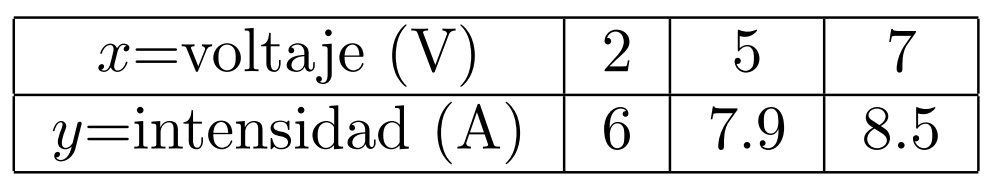

Para obtener un ajuste lineal (es decir, una recta $y=mx+n$), habría que resolver el sistema


$$\textstyle\left\{  \begin{array}{rcr}
			 2m  + n & = & 6\\ 
			 5m + n & = & 7.9\\
			 7m +n & = & 8.5\\  
		 \end{array}\right.$$


en el que las incógnitas serán $m$ y $n$ (coeficientes de la recta de ajuste). Lo resolvemos:

x0 = [2 5 7];  % coordenada x de los puntos de la nube
y0 = [6 7.9 8.5];  % coordenada y de los puntos de la nube
A = [x0', ones(length(x0), 1)]  % matriz de coeficientes del sistema a resolver
b = y0'  % vector de términos independientes del sistema a resolver
[rank(A) rank([A b])]  % S.I.

Las columnas de $A$ son L.I. ($rg(A)=2$), por lo que podemos calcular directamente la solución de mínimos cuadrados como:

xhat = inv(A'*A)*A'*b  % solución de mínimos cuadrados

El primerelemento de esta solución será el coeficiente $m$ de nuestro ajuste lineal, y el segundo la $n$. Por tanto, el polinomio aproximador buscado es $y=0.5105x+5.0842$.

## Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{R}^4$, obtén una base del complemento ortogonal del subespacio $S=\lbrace (\alpha, 0, 2\alpha, \alpha): \alpha \in \mathbb{R}\rbrace$. Verifica que $S^\perp$ es ortogonal a $S$ y que $S$ y $S^\perp$ son subespacios complementarios/suplementarios.

**Ejercicio 2:**

En $\mathbb{R}^3$, proyecta ortogonalmente el vector $\vec{v} = (3,2,2)$ sobre el subespacio $S=<(2,0,1),(0,3,-1),(2,3,0)>$ utilizando la matriz de proyección. Calcula dicha matriz partiendo de dos bases de $S$ distintas, una de ellas ortonormal y la otra no. ¿Qué sucede?

**Ejercicio 3:**

Utilizando matrices de proyección, calcula la proyección ortogonal del vector $$\vec{v} = (3, 4, 5)$$ sobre el subpespacio $S : \lbrace x-y+z=0 \rbrace$ de $\mathbb{R}^3$ y sobre $S^\perp$. Comprueba que ambas proyecciones son ortogonales entre sí y que $\vec{v}$ puede expresarse como la suma de ambas. ¿Qué pasa si sumas la matriz de proyección sobre $S$ y la matriz de proyección sobre $S^\perp$?

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.